old_atlas_path = "C:\Users\sep27\Documents\GitHub\NeuroPAL_ID\Data\Models\atlas_xx_rgb.mat";
new_atlas_path = "C:\Users\sep27\Documents\Final_atlases_v2\Final_atlases_v2\Full_atlas_matched_nosplit.pkl";

old_atlas = load(old_atlas_path);
old_model = old_atlas.atlas.head.model

old_model = struct with fields:
       mu: [195×6 double]
    sigma: [6×6×195 double]


old_names = old_atlas.atlas.head.N

old_names = 195×1 cell array
    {'ADAL' }
    {'ADAR' }
    {'ADEL' }
    {'ADER' }
    {'ADFL' }
    {'ADFR' }
    {'ADLL' }
    {'ADLR' }
    {'AFDL' }
    {'AFDR' }
    {'AIAL' }
    {'AIAR' }
    {'AIBL' }
    {'AIBR' }
    {'AIML' }
    {'AIMR' }
    {'AINL' }
    {'AINR' }
    {'AIYL' }
    {'AIYR' }
    {'AIZL' }
    {'AIZR' }
    {'ALA'  }
    {'AMSOL'}
    {'AMSOR'}
    {'AQR'  }
    {'AS1'  }
    {'AS2'  }
    {'ASEL' }
    {'ASER' }


py.importlib.import_module('pickle');
py.importlib.import_module('builtins');

fid = py.open(new_atlas_path, 'rb');
new_atlas_data = struct(py.pickle.load(fid));
new_atlas_keys = fieldnames(new_atlas_data);

for k=1:length(new_atlas_keys)
    switch class(new_atlas_data.(new_atlas_keys{k}))
        case {'py.str', 'py.list'}
            new_atlas_data.(new_atlas_keys{k}) = string(new_atlas_data.(new_atlas_keys{k}));
        case 'py.numpy.ndarray'
            new_atlas_data.(new_atlas_keys{k}) = double(new_atlas_data.(new_atlas_keys{k}));
    end
end

new_atlas = new_atlas_data

new_atlas = struct with fields:
       bodypart: "head"
             mu: [194×6 double]
          sigma: [6×6×194 double]
          names: ["RIAL"    "RIPR"    "I5"    "FLPR"    "IL1L"    "RMDL"    "IL1R"    "DB1"    "AWCR"    "RMDDL"    "IL1DL"    "AIAL"    "AIBL"    "AWAL"    "I1L"    "RMEV"    "VB1"    "CEPVR"    "VB3"    "RIGL"    "ASGR"    …    ] (1×194 string)
        aligned: [194×6×104 double]
    description: "Atlas trained using all data from NP orginal, Yemini 21, Foco, Ray, Chaudhary, Kimura datasets, Flavell. Histogram matched, Z-scored, and median sampled"


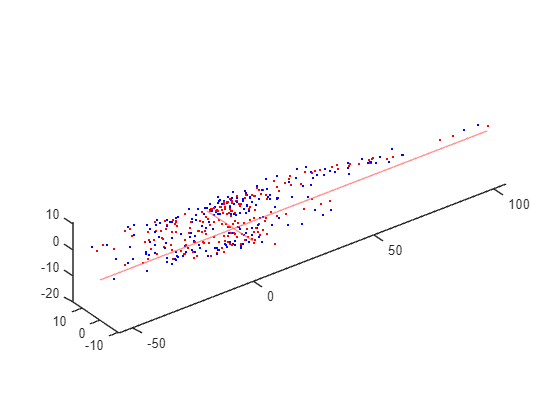

old_coords = old_model.mu(:, 1:3);
new_coords = new_atlas.mu(:, 1:3);
rotate = 1;
flip_z = 1;
center_0 = 1;

% Rotate
if rotate
    new_coords(:, 1) = new_atlas.mu(:, 2);
    new_coords(:, 2) = new_atlas.mu(:, 1);
end

% Flip vertically
if flip_z
    new_coords(:, 3) = -new_coords(:, 3);
end

% Center around 0
if center_0
    new_coords(:, 1) = new_coords(:, 1)-mean(new_coords(:, 1));
    new_coords(:, 2) = new_coords(:, 2)-mean(new_coords(:, 2));
    new_coords(:, 3) = new_coords(:, 3)-mean(new_coords(:, 3));
end

figure
hold on
xline(mean(new_coords(:, 1)), 'Color', [1 0.4 0.4])
yline(mean(new_coords(:, 2)), 'Color', [1 0.4 0.4])
scatter3(old_coords(:, 1), old_coords(:, 2), old_coords(:, 3), 3, 'red', 'filled');
scatter3(new_coords(:, 1), new_coords(:, 2), new_coords(:, 3), 3, 'blue', 'filled');
daspect([1 1 1])
view(3)
hold off

old_atlas.atlas.head.N

ans = 195×1 cell array
    {'ADAL' }
    {'ADAR' }
    {'ADEL' }
    {'ADER' }
    {'ADFL' }
    {'ADFR' }
    {'ADLL' }
    {'ADLR' }
    {'AFDL' }
    {'AFDR' }
    {'AIAL' }
    {'AIAR' }
    {'AIBL' }
    {'AIBR' }
    {'AIML' }
    {'AIMR' }
    {'AINL' }
    {'AINR' }
    {'AIYL' }
    {'AIYR' }
    {'AIZL' }
    {'AIZR' }
    {'ALA'  }
    {'AMSOL'}
    {'AMSOR'}
    {'AQR'  }
    {'AS1'  }
    {'AS2'  }
    {'ASEL' }
    {'ASER' }


new_atlas.names = cellstr(new_atlas.names')

new_atlas = struct with fields:
       bodypart: "head"
             mu: [194×6 double]
          sigma: [6×6×194 double]
          names: {194×1 cell}
        aligned: [194×6×104 double]
    description: "Atlas trained using all data from NP orginal, Yemini 21, Foco, Ray, Chaudhary, Kimura datasets, Flavell. Histogram matched, Z-scored, and median sampled"


old_atlas.atlas.head.model.mu = new_atlas.mu;
old_atlas.atlas.head.model.sigma = new_atlas.sigma;
old_atlas.atlas.head.N = new_atlas.names;

[~, pname, pfmt] = fileparts(old_atlas_path);
fname = strrep(old_atlas_path, pfmt, sprintf("_new%s", pfmt));
save(fname, '-struct', 'old_atlas')

load(fname)